%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =   4.701e-34  (3.645e-34, 5.757e-34)
  %     p2 =   6.621e-16  (-2.342e-17, 1.348e-15)

%Goodness of fit:
 % SSE: 1.031e-31
 % R-square: 0.9745
 % Adjusted R-square: 0.9681
 % RMSE: 1.606e-16
 
[xData, yData] = prepareCurveData( freq, Energy );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

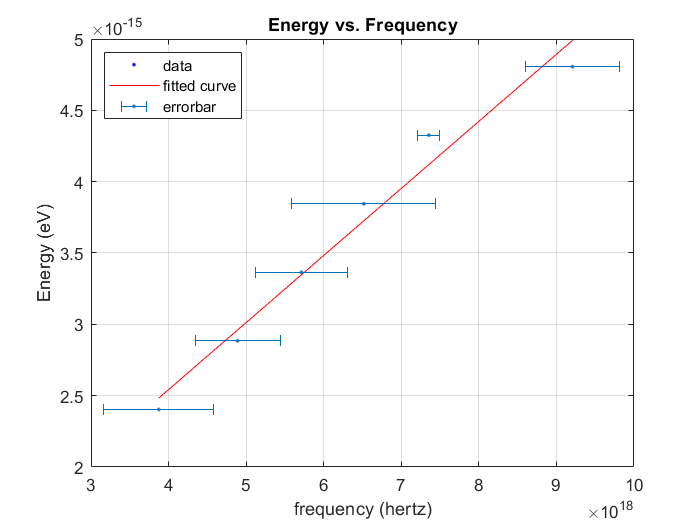


% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
hold on
grid on

error=1e+18.*[0.708 0.547 0.598 0.93 0.140 0.609];
errorbar(freq,Energy,error,'horizontal','.')

legend({'data','fitted curve','errorbar'},'Location','northwest')
title('Energy vs. Frequency')
xlabel('frequency (hertz)')
ylabel('Energy (eV)')